clc;clear;
load("EEI_DATA_90_200_1000.mat");
x90 = EEI_DATA.x;
y90 = EEI_DATA.y;
load("EEI_DATA_100_200_1000.mat");
x100 = EEI_DATA.x;
y100 = EEI_DATA.y;

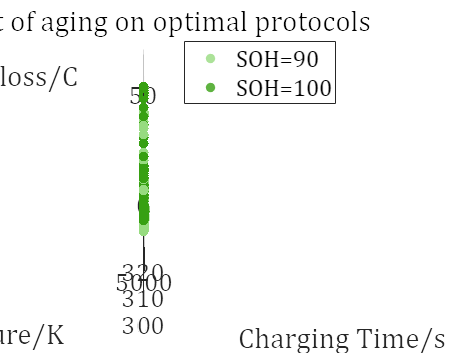

close(figure(1));
figure(1);
scatter3(y90(:,1),y90(:,2),y90(:,3),40,...
    'MarkerFaceColor','#97DB80','MarkerFaceAlpha',0.8,...
    'MarkerEdgeColor','#97DB80','MarkerEdgeAlpha',0.5)
hold on
scatter3(y100(:,1),y100(:,2),y100(:,3),40,...
    'MarkerFaceColor','#37A012','MarkerFaceAlpha',0.8,...
    'MarkerEdgeColor','#37A012','MarkerEdgeAlpha',0.5)
hold off
xlabel('Charging Time/s');ylabel('Temperature/K');zlabel('lithium-ion loss/C');
legend('SOH=90','SOH=100');
% xlim([0,6000]);ylim([300,330]);zlim([15,80]);
set(gca,'fontname','Cambria','fontsize',18);
title("Impact of aging on optimal protocols");